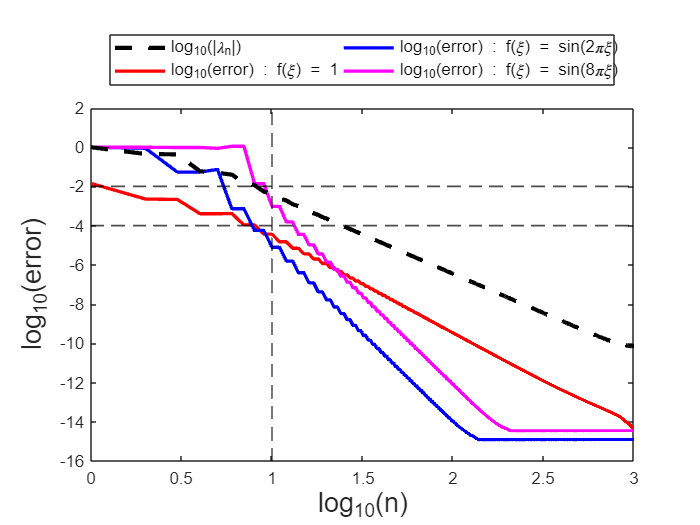

N = 1000;
modal_approximations = zeros(1, N);
modal_components = zeros(1, N);
eta = exp(-pi*1i/8);

xi_values = (2*(1:N) - 1)./(2*N);
Sp = 3;
k = 0.72;

        G_prime = zeros(N, N);
        cosines = zeros(N, N);
        sines = zeros(N, N);
        
        
        %phi_of_xi = zeros(1, length(xi_values));
        phi_of_xi = 2*pi*k*xi_values;
        
        
        for b = 1:N
            xi = xi_values(b);
            x_minus = xi_values(1:b);
            x_plus = xi_values(b:N);
        
            M = [1 1 1 1 0 0 0 0; 1 1i -1 -1i 0 0 0 0; 0 0 0 0 exp(Sp*eta) exp(Sp*eta*1i) exp(-Sp*eta) exp(-Sp*eta*1i); 0 0 0 0 exp(Sp*eta) 1i*exp(Sp*eta*1i) -exp(-Sp*eta) -1i*exp(-Sp*eta*1i); -exp(Sp*eta*xi) -exp(Sp*eta*1i*xi) -exp(-Sp*eta*xi) -exp(-Sp*eta*1i*xi) exp(Sp*eta*xi) exp(Sp*eta*1i*xi) exp(-Sp*eta*xi) exp(-Sp*eta*1i*xi);  -exp(Sp*eta*xi) -1i*exp(Sp*eta*1i*xi) exp(-Sp*eta*xi) 1i*exp(-Sp*eta*1i*xi) exp(Sp*eta*xi) 1i*exp(Sp*eta*1i*xi) -exp(-Sp*eta*xi) -1i*exp(-Sp*eta*1i*xi);  -exp(Sp*eta*xi) exp(Sp*eta*1i*xi) -exp(-Sp*eta*xi) exp(-Sp*eta*1i*xi) exp(Sp*eta*xi) -exp(Sp*eta*1i*xi) exp(-Sp*eta*xi) -exp(-Sp*eta*1i*xi);  -exp(Sp*eta*xi) 1i*exp(Sp*eta*1i*xi) exp(-Sp*eta*xi) -1i*exp(-Sp*eta*1i*xi) exp(Sp*eta*xi) -1i*exp(Sp*eta*1i*xi) -exp(-Sp*eta*xi) 1i*exp(-Sp*eta*1i*xi)];
            coeff = linsolve(M, [0; 0; 0; 0; 0; 0; 0; 1/((Sp^3)*(eta^3))]);
        
            G_prime((1:b),b) = Sp*eta*(coeff(1)*exp(Sp*eta*x_minus) + 1i*coeff(2)*exp(Sp*eta*x_minus*1i) - coeff(3)*exp(-Sp*eta*x_minus) - 1i*coeff(4)*exp(-Sp*eta*x_minus*1i));
        
            G_prime((b:N),b) = Sp*eta*(coeff(5)*exp(Sp*eta*x_plus) + 1i*coeff(6)*exp(Sp*eta*x_plus*1i) - coeff(7)*exp(-Sp*eta*x_plus) - 1i*coeff(8)*exp(-Sp*eta*x_plus*1i));
        
            cosines(:, b) = cos(phi_of_xi - phi_of_xi(b));
            sines(:, b) = sin(phi_of_xi - phi_of_xi(b));
        
        end
        G_s = -0.5*(imag(G_prime) + imag(G_prime.'));
        G_a = -0.5*(real(G_prime) - real(G_prime.'));
        
        G_swim = G_s.*cosines + G_a.*sines;
        
        [A, B] = eig(G_swim);
        eigenvalues = diag(B)/N;

        [~, order] = sort(abs(eigenvalues));

        eigenfunctions = A(:, flip(order))*sqrt(N);
        eigenvalues = eigenvalues(flip(order));

temp = log10(abs(eigenvalues/eigenvalues(1)));
plot(log10(1:N), temp, '--k', 'LineWidth', 2.5)
hold on

f = ones(1, N);

for n = 1:N
    modal_components(n) = f*eigenfunctions(:, n)/N;
    modal_approximations(n) = modal_components(n)^2*eigenvalues(n);
end

for n = 2:N
    modal_approximations(n) = modal_approximations(n) + modal_approximations(n-1);
end

actual_swimming_speed = (f*G_swim)*f.'/N^2;
plot(log10(1:N), log10(abs(modal_approximations/actual_swimming_speed - 1)), 'r', 'LineWidth', 2)

f = sin(2*pi*xi_values);

for n = 1:N
    modal_components(n) = f*eigenfunctions(:, n)/N;
    modal_approximations(n) = modal_components(n)^2*eigenvalues(n);
end

for n = 2:N
    modal_approximations(n) = modal_approximations(n) + modal_approximations(n-1);
end

actual_swimming_speed = (f*G_swim)*f.'/N^2;
plot(log10(1:N), log10(abs(modal_approximations/actual_swimming_speed - 1)), 'b', 'LineWidth', 2)

f = sin(8*pi*xi_values) - 0.5*eigenfunctions(:, n).'/N;

for n = 1:N
    modal_components(n) = f*eigenfunctions(:, n)/N;
    modal_approximations(n) = modal_components(n)^2*eigenvalues(n);
end

for n = 2:N
    modal_approximations(n) = modal_approximations(n) + modal_approximations(n-1);
end

actual_swimming_speed = (f*G_swim)*f.'/N^2;
plot(log10(1:(N-1)), log10(abs(modal_approximations(1:end-1)/actual_swimming_speed - 1)), 'm', 'LineWidth', 2)

xlabel('log_{10}(n)', 'fontsize', 16)
ylabel('log_{10}(error)', 'fontsize', 16)
xline(1, '--k', 'LineWidth', 1)
yline(-2, '--k', 'LineWidth', 1)
yline(-4, '--k', 'LineWidth', 1)
legend('log_{10}(|\lambda_n|)', 'log_{10}(error) : f(\xi) = 1', 'log_{10}(error) : f(\xi) = sin(2\pi\xi)', 'log_{10}(error) : f(\xi) = sin(8\pi\xi)', 'Fontsize', 10, 'Location', 'NorthOutside', 'AutoUpdate', 'off', 'NumColumns', 2)
plot(log10(1:N), temp, '--k', 'LineWidth', 2.5)
ylim([-16, 2])
yticks(-16:2:2)
xlim([0, 3])
xticks(0:0.5:3)


% f1 = sin(pi*xi_values);
% 
% for n = 1:N
%     modal_components(n) = f1*eigenfunctions(:, n)/N;
%     modal_approximations(n) = modal_components(n)^2*eigenvalues(n);
% end
% 
% for n = 2:N
%     modal_approximations(n) = modal_approximations(n) + modal_approximations(n-1);
% end
% 
% actual_swimming_speed = (f1*G_swim)*f1.'/N^2;
% plot(log(1:N), log(abs(modal_approximations/actual_swimming_speed - 1)), 'r', 'LineWidth', 2)
% 
% 
% f2 = sin(2*pi*xi_values);
% 
% for n = 1:N
%     modal_components(n) = f2*eigenfunctions(:, n)/N;
%     modal_approximations(n) = modal_components(n)^2*eigenvalues(n);
% end
% 
% for n = 2:N
%     modal_approximations(n) = modal_approximations(n) + modal_approximations(n-1);
% end
% 
% actual_swimming_speed = (f2*G_swim)*f2.'/N^2;
% plot(log(1:N), log(abs(modal_approximations/actual_swimming_speed - 1)), 'r', 'LineWidth', 2)



